# What should the basis functions be for fitting the raw lip signals?

This is similar to the tongue function (s_oeBloodFluorophoreTongue).  But the lip does not have porphyrins or keratin.

Some fluorophores are present at different tissue layers.  The superficial layers (epithelial) contain FAD and NADH in certain locations.  These are not going to be impacted by blood absorptions.  The blood is below the epithelial layer.

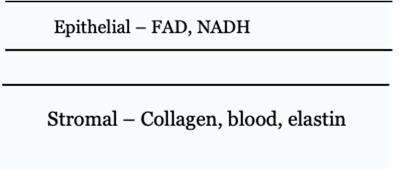

We have multiple data about the emissions of each of these fluorophores in the isetfluorescence repository.  We read them in and we also read in raw data taken from our subjects' lips.  

Each of the fluorophores has several reports in the literature.  We chose which fluorophores to use in the script s_oeFluorophoreBasis.mlx.

This script will explore how we might create basis functions to predict the raw data as weighted sums of the fluorophore excitations, but combining them as if some of the fluorophores are passing through blood.

The reason we think blood is necessary is because the raw data - directory spectral photometry measures from the tongue and lip - show some signs of the dips that are well known to be part of the blood absorbance (transmittance) measured in different contexts.

To support the calculations of absorbance and transmittance we created a Matlab class called 'medium', which helps us keep track of the relationship between absorbance, absorptance, transmittance and optical density.

## Programming notes

Repositories: isetcam, isetfluorescence and oe_tongue_lip

3/4 of the blood is oxygenated.  We might add in deoxy_ in the future.

## Initialize

Different analyses are based on different wavebands.

ieInit;
wave = 500:600;
normWave = 520;
yscale = 'linear';

## Read a couple of raw data sets

This is the database of raw measurements.

[T,dataDir] = oeDatabaseCreate;

We illustrate with Z's data because he has little porphyrin. 

These are measurements with different excitation lights at max intensity.  All the subjects show the peak shift from 500 to 515 as the excitation light changes from 405 to 450.

Also, notice the very large dip on the lip around 580, but not on the tongue. 

Something to remember when we write.  When you measure samples, or with an endoscope, you may be able to see different fluorophores.  The global (raw) signal, however, may be dominated by one of the fluorophores with only relatively small contributions from the others.  In this case, it appears that collagen through oxygen is the dominant signal in 500-600 band.

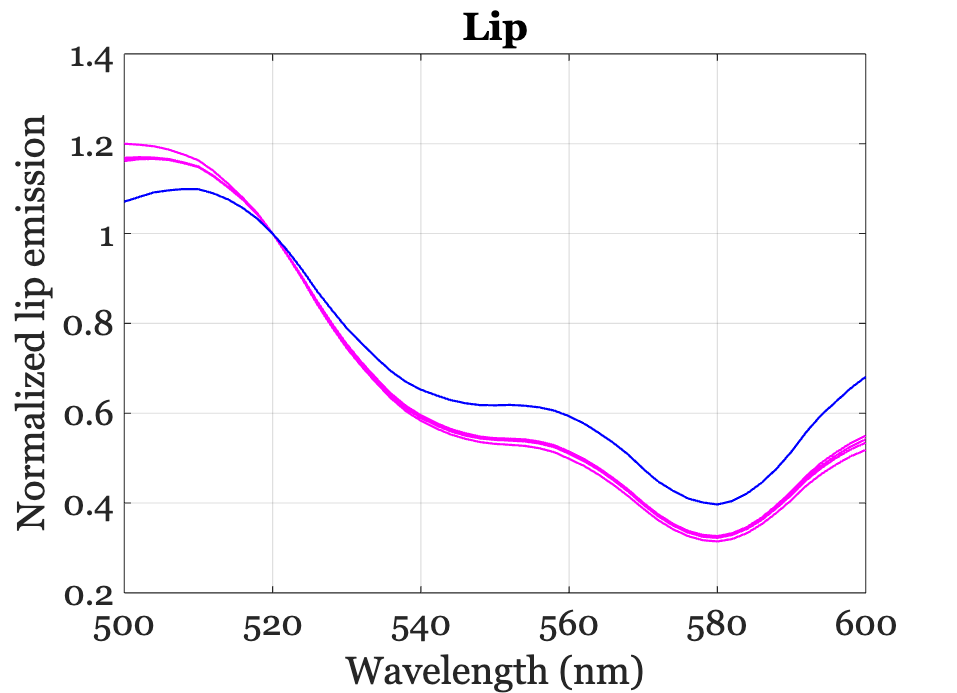

files405 = ieTableGet(T,'subject','B','substrate','lip','e wave',405,'e level',980);
files415 = ieTableGet(T,'subject','B','substrate','lip','e wave',415,'e level',910);
lipFiles = cat(1,files405,files415);

lipData405 = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);

files450 = ieTableGet(T,'subject','B','substrate','lip','e wave',450,'e level',870);
lipData450 = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);

ieNewGraphWin;
hA = plot(wave,lipData405,'m-'); hold on;
hB = plot(wave,lipData450,'b-'); hold on;
grid on;
title('Lip');
xlabel('Wavelength (nm)'); ylabel('Normalized lip emission'); grid on;

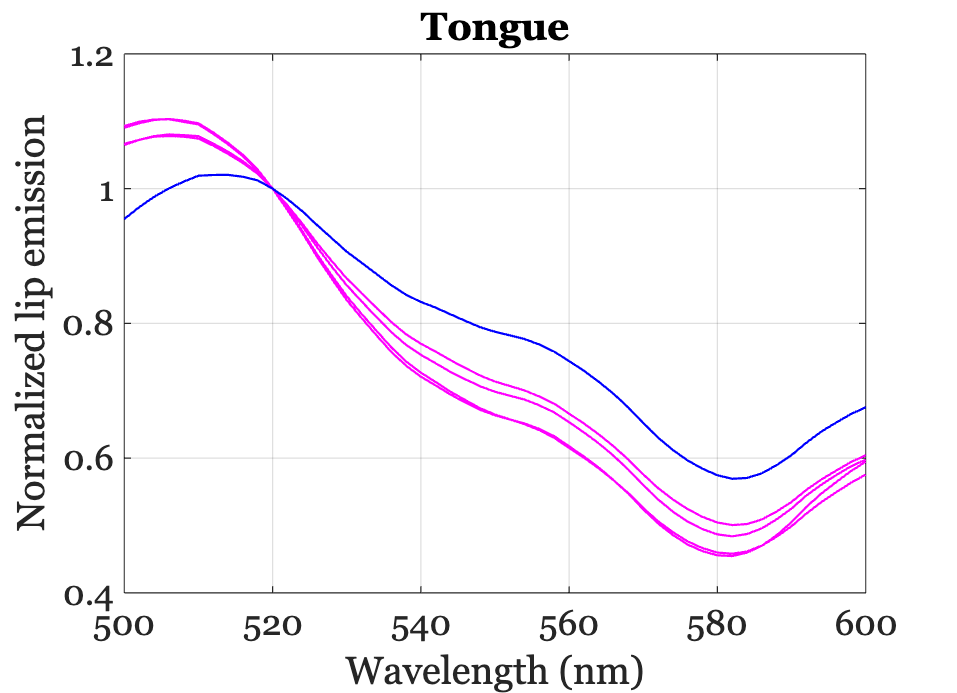

% legend({'405','450'});

% Now the tongue
files405 = ieTableGet(T,'subject','B','substrate','tongue','e wave',405,'e level',980);
files415 = ieTableGet(T,'subject','B','substrate','tongue','e wave',415,'e level',910);
tongueFiles = cat(1,files405,files415);

tongueData405 = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);

files450 = ieTableGet(T,'subject','B','substrate','tongue','e wave',450,'e level',870);
tongueData450 = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);

ieNewGraphWin;
hA = plot(wave,tongueData405,'m-'); hold on;
hB = plot(wave,tongueData450,'b-'); hold on;
grid on;
title('Tongue');
xlabel('Wavelength (nm)'); ylabel('Normalized lip emission'); grid on;

## Select the fluorophores and read oxy medium

Above, we plasted all the fluorophore emissions data in a matrix (fluorophores).  We check how well the full matrix can predict the data samples.  We think it won't without accounting for blood.  

The formula is simple for the full linear calculation


$$d=\textrm{Fw}$$


We have many fluorophore files from the literature. These are analyzed in s_LoadFluorophoreEmissions.  

Apart from FAD, all of the fluorophore emission spectra decline in the wave band from 500-600nm.  They exact emissions differ between labs, but the slopes are similar.

For the lip, there is no keratin, porphyrins, or chlorophyll.  We selected which to use in the s_oeBloodFluorophoreBasis.mlx script.

% Always put the collagen in the first column

% fluorophoreNames = {'CollagenWuQu','NADH_webfluor','FADLin'};
% fluorophoreNames = {'CollagenWuQu','FADLin'};  
% fluorophoreNames = {'CollagenWuQu','FADValdez'}; 
% fluorophoreNames = {'elastin_webfluor','FADValdez'}; 
% Rises a bit
fluorophoreNames = {'collagen7','elastin_webfluor','FADValdez'}; 
% fluorophoreNames = {'collagen1','elastin_webfluor','FADValdez'}; 

% fluorophoreNames = {'CollagenWuQu','elastin_webfluor','FADValdez'}; 
[fluorophores,wave] = fiLoadBasis(fluorophoreNames,'wave',wave);

% Here is oxy
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);


## Read in the oxy data

Let's amend the fluorophore basis by adding in collagen and elastin after some filtering by blood.  Notice that the blood has the two characteristic dips at 540 nm and 580nm.  We see little bumps like that in the raw data (above).

For different purposes we might choose different wavebands.  The raw data are pretty much good from 500-670 or so.  The wavelengths above 600 nm are mainly porphyrin fluorescence (bacteria on the tongue).

We only consider oxygenated blood now because 100% of the blood from the heart lung is oxygenated, and about 50% of the blood in the veins is also oxygenated. 

%{
ieNewGraphWin;
for od = (0.5:0.2:2)
    oxyblood.opticalDensity = od;
    plot(wave,oxyblood.transmittance); hold on;
end
grid on; xlabel('Wavelength (nm)'); ylabel('Transmittance');
%}

## Apply blood transmittance

This should also become a function that takes a fluorophore and modifies it by blood transmittance with some arguments.  We experimented and it seemed we only needed elastin with a blood density of 2.5.  We might try using the fminsearch() method to fit the optical density.

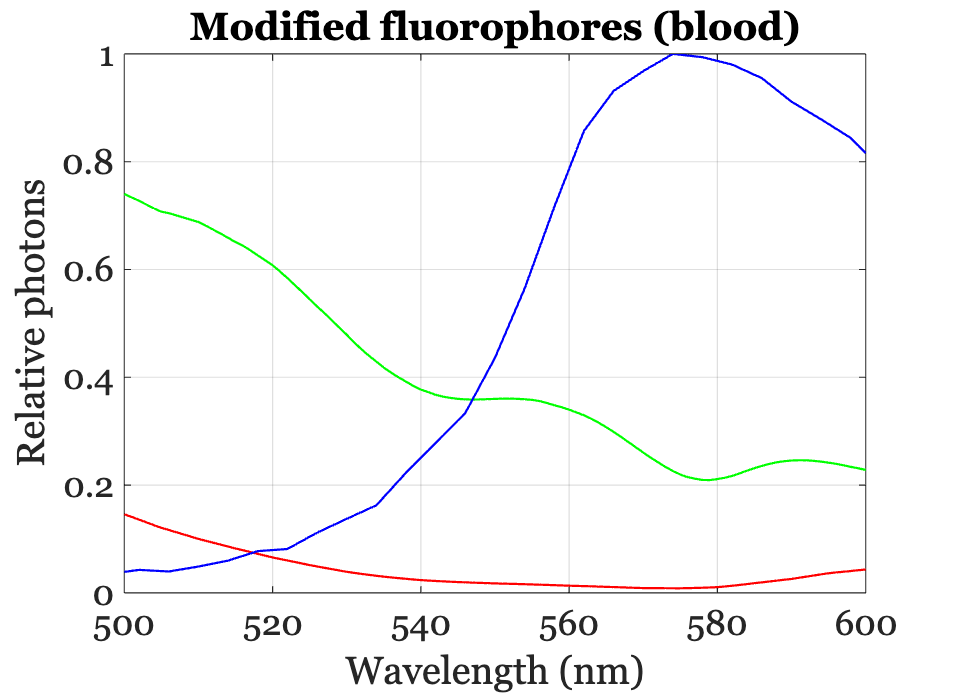

oxyblood.opticalDensity = 2.0;

transmittance = oxyblood.transmittance;

fluorophores(:,1) = fluorophores(:,1).* transmittance(:);
fluorophores(:,2) = fluorophores(:,2).* transmittance(:);

ieNewGraphWin;
plot(wave,fluorophores); title('Modified fluorophores (blood)')
xlabel('Wavelength (nm)'); ylabel('Relative photons'); grid on;

## **Lip: non-negative with oxygen**

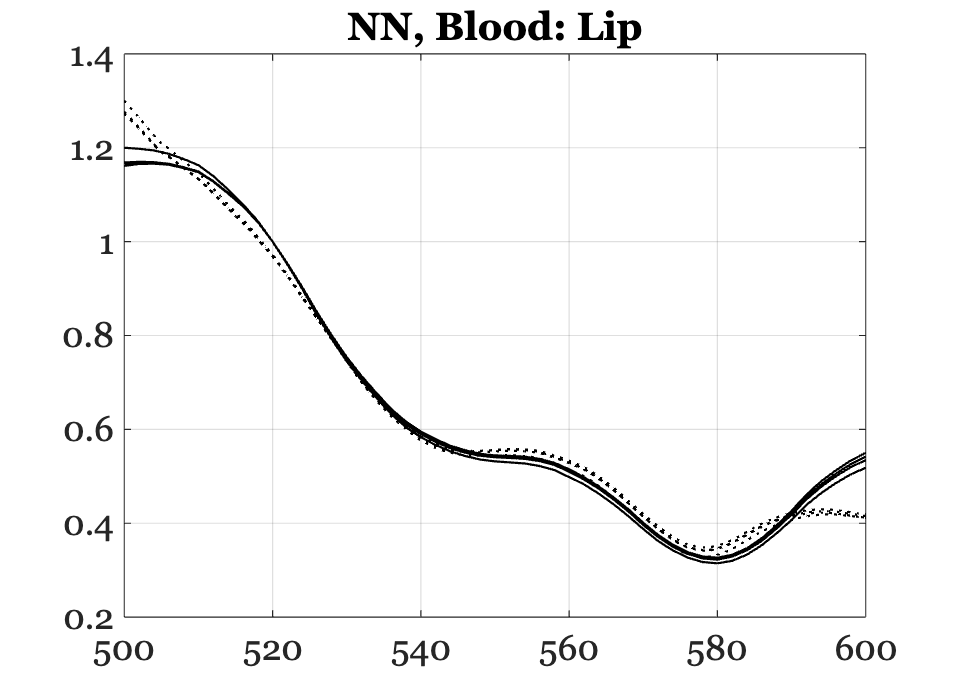

wgtsNN = zeros(size(fluorophores,2),size(lipData,2));

for dd = 1:size(lipData,2)
    wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
end

ieNewGraphWin;
plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
grid on; title('NN, Blood: Lip')

disp(fluorophoreNames'); disp(wgtsNN);

    {'collagen7'       }
    {'elastin_webfluor'}
    {'FADValdez'       }

    1.7822    1.5122    1.4631    1.3902
    1.4044    1.4254    1.4309    1.4443
    0.0171    0.0299    0.0348    0.0259



## Lips

Fit for lips here. Ordinary least squares.

% lipData = lipData405;
% % lipData = lipData450;
% wgtsLS = pinv(fluorophores)*lipData;
% 
% ieNewGraphWin;
% plot(wave,lipData,'k-',wave,fluorophores*wgtsLS,'k:');
% grid on;
% legend({'Lip data','LS est'});

## **Non-negative lip**

The LS fits are close, but they have negative values for the different fluorophore contributions.  We don't think that is OK.  So we force the solutions to be nonnegative using this method.  

% wgtsNN = zeros(size(fluorophores,2),size(lipData,2));
% 
% for dd = 1:size(lipData,2)
%     wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
% end
% 
% ieNewGraphWin;
% plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
% grid on; title('NN: Lip')
